## Road Profile - Generation

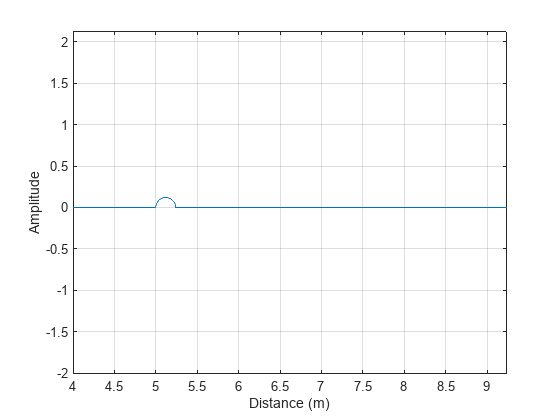

[X_r, Z_r] = bump_road_input(5,0.12,15);


profile_length = 200;       % Length of the road profile (meters)
sampling_rate = 50;        % Numberof points per meter
amplitude_factor = 0.005;     % Roughness
num_bumps = 5;             % Number of bumps
bump_amplitude = 0.001;       % Amplitude of bumps
bump_frequency = 0.5;       % Frequency of bumps

[X_r, Z_r] = generateRoadProfileWithBumps(profile_length, sampling_rate, amplitude_factor, num_bumps, bump_amplitude, bump_frequency);

road.X_r = X_r;
road.Z_r = Z_r;

## Car Model

%Vehicle
scooter.mass = 150;    
scooter.front_unsprung_mass = 15;       
scooter.rear_unsprung_mass = 15;    
scooter.Lateral_MOI = 20;    
scooter.CG_2_Front = 0.5;      
scooter.CG_2_Rear = 0.5;    



stiffness.front_strut = 15000;  
stiffness.rear_strut = 15000;   
stiffness.tire_front = 100000;
stiffness.tire_rear = 100000;

damping.strut_front = 1000;
damping.strut_rear = 1000;

%Velocity
initial_vel = 10; %velocity in m/s
acc  = 0;

## SOLVING

[displacement, velocity, acceleration] = Ride_Comfort_Analysis(scooter, stiffness, damping, road, initial_vel, acc)

displacement = struct with fields:
                    z_body: [300×1 double]
          z_unsprung_front: [300×1 double]
           z_unsprung_rear: [300×1 double]
                     theta: [300×1 double]
                      time: [300×1 double]
                tire_front: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
                 tire_rear: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
    longitudinal_pos_front: [1 1.0334 1.0669 1.1003 1.1338 1.1672 1.2007 1.2341 1.2676 1.3010 1.3344 1.3679 1.4013 1.4348 1.4682 1.5017 1.5351 1.5686 1.6020 1.6355 1.6689 1.7023 1.7358 1.7692 1.8027 1.8361 1.8696 1.9030 1.9365 1.9699 2.0033

velocity = struct with fields:
              v_body: [299×1 double]
    v_unsprung_front: [299×1 double]
     v_unsprung_rear: [299×1 double]
            v_thetha: [299×1 double]
                time: [299×1 double]


acceleration = struct with fields:
              a_body: [298×1 double]
    a_unsprung_front: [298×1 double]
     a_unsprung_rear: [298×1 double]
             a_theta: [298×1 double]
                time: [298×1 double]


%ANd DONEEEEEEEE...

## **Plotting & Analyzing**

**Position Based Analysis**

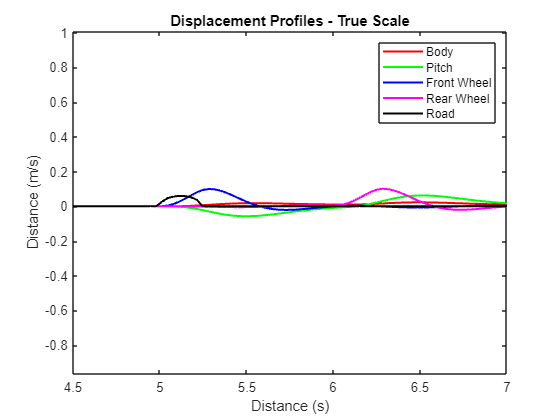

figure
u = displacement.longitudinal_pos_front;
plot(u , displacement.z_body, 'r', 'LineWidth', 1.5);
hold on;
plot(u, displacement.theta, 'g', 'LineWidth', 1.5);
plot(u, displacement.z_unsprung_front, 'b', 'LineWidth', 1.5);
plot(u, displacement.z_unsprung_rear, 'm', 'LineWidth', 1.5);
plot(u, displacement.tire_front, 'k', 'LineWidth', 1.5);
xlabel('Distance (s)');
ylabel('Distance (m/s)');
legend('Body', 'Pitch', 'Front Wheel', 'Rear Wheel','Road');
title('Displacement Profiles - True Scale');
axis equal
xlim([4.5 7])
hold off

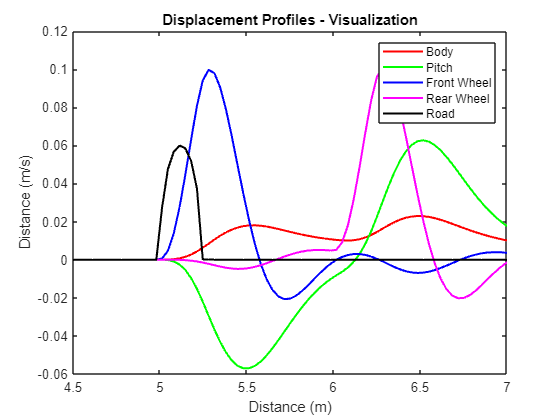

figure
u = displacement.longitudinal_pos_front;
plot(u , displacement.z_body, 'r', 'LineWidth', 1.5);
hold on;
plot(u, displacement.theta, 'g', 'LineWidth', 1.5);
plot(u, displacement.z_unsprung_front, 'b', 'LineWidth', 1.5);
plot(u, displacement.z_unsprung_rear, 'm', 'LineWidth', 1.5);
plot(u, displacement.tire_front, 'k', 'LineWidth', 1.5);
xlabel('Distance (m)');
ylabel('Distance (m/s)');
legend('Body', 'Pitch', 'Front Wheel', 'Rear Wheel','Road');
title('Displacement Profiles - Visualization');
xlim([4.5 7])
hold off

**Time Based Analysis**

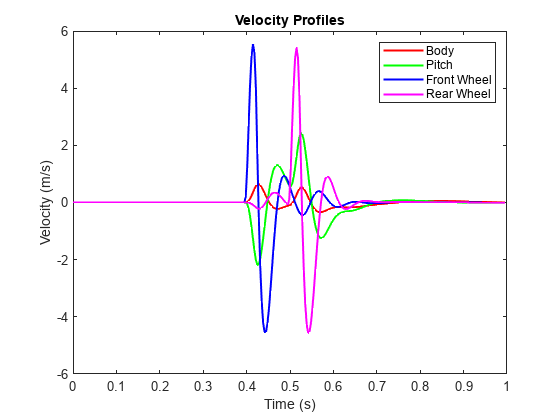

figure;
plot(velocity.time, velocity.v_body, 'r', 'LineWidth', 1.5);
hold on;
plot(velocity.time, velocity.v_thetha, 'g', 'LineWidth', 1.5);
plot(velocity.time, velocity.v_unsprung_front, 'b', 'LineWidth', 1.5);
plot(velocity.time, velocity.v_unsprung_rear, 'm', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend('Body', 'Pitch', 'Front Wheel', 'Rear Wheel');
title('Velocity Profiles');
hold off

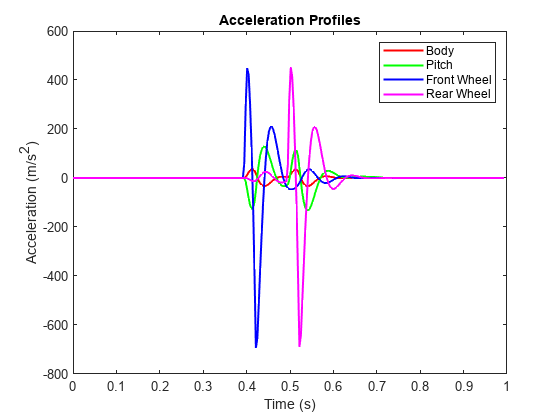


figure;
plot(acceleration.time, acceleration.a_body, 'r', 'LineWidth', 1.5);
hold on;
plot(acceleration.time, acceleration.a_theta, 'g', 'LineWidth', 1.5);
plot(acceleration.time, acceleration.a_unsprung_front, 'b', 'LineWidth', 1.5);
plot(acceleration.time, acceleration.a_unsprung_rear, 'm', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend('Body', 'Pitch', 'Front Wheel', 'Rear Wheel');
title('Acceleration Profiles');
hold off

## RIDE COMFORT QUANTIZATION

Root Mean Square Acceleration

%Body
RMS_Acc_Body = rms(acceleration.a_body)

RMS_Acc_Body = 9.0862

%Pitch
RMS_Acc_Pitch = rms(acceleration.a_theta)

RMS_Acc_Pitch = 34.0564

Transmissibility (acceleration based)

max(acceleration.a_body)/max(acceleration.a_unsprung_front)

ans = 0.0800

Power Spectral Density - Frequency based

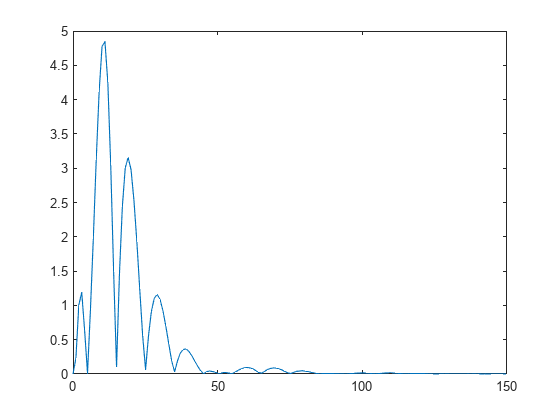

[Weighted_PSD, frequency_arr, PSD] = Frequency_analysis(acceleration.a_body,acceleration.time);
plot(frequency_arr, PSD)

Total Power (PSD integral)

Total_Power = trapz(frequency_arr, PSD)

Total_Power = 62.4977

Finding Natural Frequencies

% Find and display the first 5 peaks in the amplitude spectrum (simple peak detection)
peaks = [];
locs = [];

for i = 2:length(frequency_arr)-1
    if PSD(i) > PSD(i-1) && PSD(i) > PSD(i+1)
        peaks = [peaks, PSD(i)];
        locs = [locs, frequency_arr(i)];
    end
end

n_modes = 5;

Natural Frequencies (First 5)

peaks = peaks(1:n_modes);
freqs = locs(1:n_modes)

freqs =     3.0101   11.0369   19.0638   29.0973   39.1309


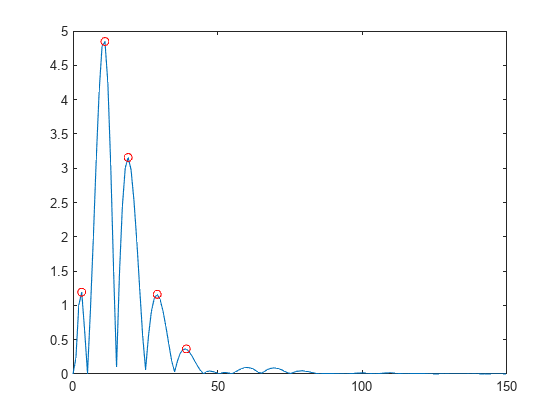


plot(frequency_arr, PSD)
hold on;
plot(freqs, peaks, 'ro');
hold off;